# Calibrate Credit Risk Function

## Generalized Logistic Function


$$q_t = \underline q + \left(\overline q - \underline q\right) \left[ \frac{1}{1 + \exp-\frac{z-\mu}{\sigma} } \right]^{\exp\nu}$$


## Clear Workspace


close all
clear

figure( );


## Vector of Macro Conditions


z = linspace(-0.08, 0.05, 100);


## Choose Parameters and Plot Function

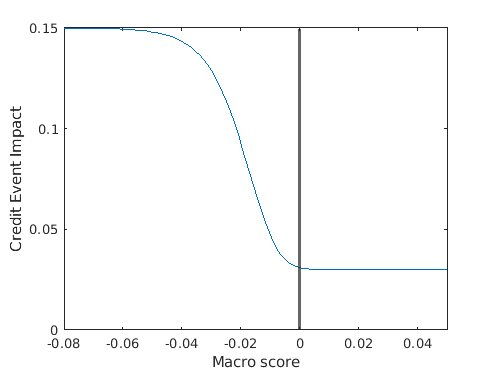

% Location parameter
mu = -0.005 ;

% Scale parameter (dispersion)
sigma = 0.008;

% Shape parameter (symmetry)
nu = 1.51;

% Lower bound
low = 0.03;

% Distance between upper and lower
height = 0.12;

% Upper bound
high = low + height;


%% Plot CDF 

figure();
% subplot(2, 1, 1);
plot(z, glogc(-z, -mu, sigma, nu, low, high));
set(gca( ), "XLim", [min(z), max(z)], "YLim", [0, high]);
xline(0, "LineWidth", 2);
xlabel("Macro score");
ylabel("Credit Event Impact");

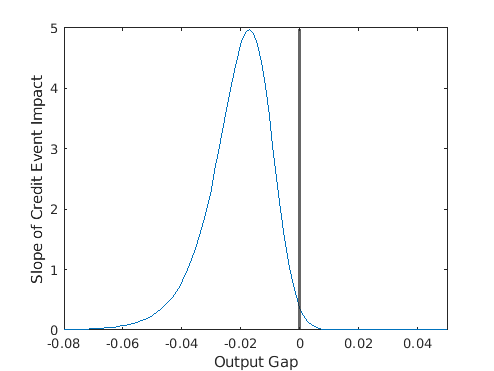


% Plot slope of the function

figure();
% subplot(2, 1, 2);
plot(z, glogd(-z, -mu, sigma, nu, low, high));
set(gca( ), "XLim", [min(z), max(z)]);
xline(0, "LineWidth", 2);
xlabel("Output Gap");
ylabel("Slope of Credit Event Impact");



disp("Slope at zero");

Slope at zero


disp(glogd(0, -mu, sigma, nu, low, high));

    0.3751

